% Set the paths to navigate between code and data
cd ../..
cur_path = pwd;
code_path = append(cur_path, '/Code/Matlab/');
addon_path = append(code_path, '/addon_path/');
data_path = append(cur_path, '/Data/');
results_path = append(cur_path, '/Results/')

results_path = '/home/tofu/Documents/Research/TopographyOfSynchrony/Results/'

workspace_path = append(code_path,'/workspaceVariables/');
% Add saved addons to MATLAB path and root path
% mr_path = matlabroot;
% mv(addon_path/., )
% addpath(addon_path);

% Change to the directory containing class definition of READ
cd(code_path);
% Read in info from MODIS dataset and customized kml containing scenes
input = READ(cur_path, code_path, data_path, results_path);

% Confirm folder extists for runtime variables that need to be offloaded
if ~isfolder('workspaceVariables')
  mkdir('workspaceVariables');
end  % else block 

% Define a variable for the DATA object made by the read class
allData = input.allData;

% Set the scenes within the data object
setScenes(allData);

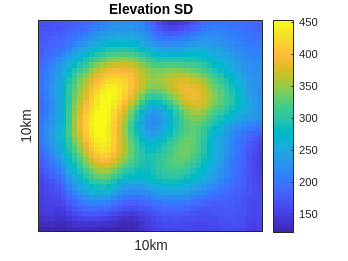

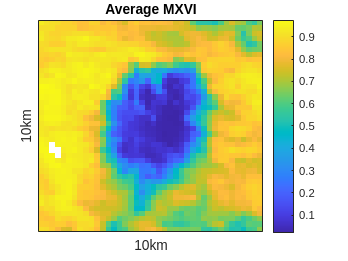

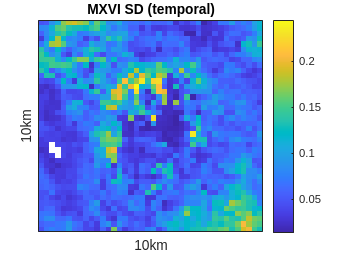

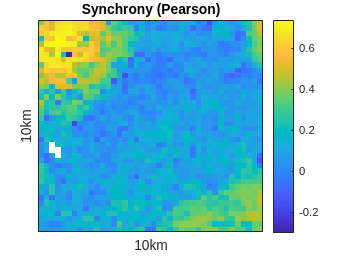

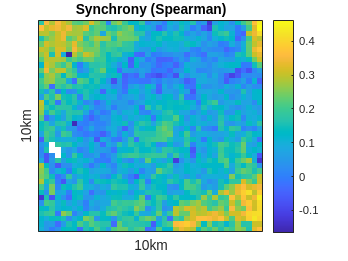

% Set the maps for each scene and export results
exportSceneData(allData);